% function visualizeResults(mCapWalkResults, dataInput, paramSetWFA)

% input arguments:
% output arguments:
%
%======================================================================


%% argument validation
mCapWalkResults

mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


dataInput
paramSetWFA

% end

%======================================================================

%% preparation
uniqMktCap = paramSetWFA.uniqMktCap;


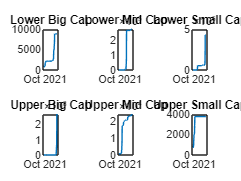

%% main function

% plot tiledlayout signal and equityCurve for each symMCapCateg

% plot tradeSignalPerSymOST
figure
tiledlayout(2,3);
for mCapIdx = 1:numel(uniqMktCap)
    nexttile;
    tradeSignalPerSymOST = ret2tick(mCapWalkResults{mCapIdx}.tradeSignalPerSymOST);
    plot(tradeSignalPerSymOST.Time, sum(tradeSignalPerSymOST.Variables,2));
    title(mCapWalkResults{mCapIdx}.mCap);

end

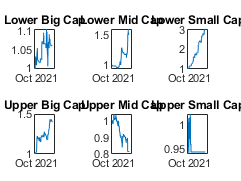



% plot portCumRetOST
figure
tiledlayout(2,3);
for mCapIdx = 1:numel(uniqMktCap)
    nexttile;
    portCumRetOST = ret2tick(mCapWalkResults{mCapIdx}.portRetOST);
    plot(portCumRetOST.Time, portCumRetOST.Variables);
    title(mCapWalkResults{mCapIdx}.mCap);

end

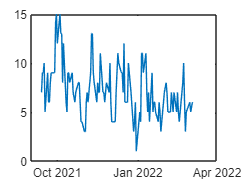


% plot tiledlayout signal and equityCurve for a combined symMCapCateg
% combine all signal

% preallocate
tradeSignalPerSymOSTCombined = mCapWalkResults{1}.tradeSignalPerSymOST;
tradeSignalPerSymOSTCombined.Variables = zeros(size(tradeSignalPerSymOSTCombined.Variables));

for mCapIdx = 1:numel(uniqMktCap)
    tradeSignalPerSymOST = mCapWalkResults{mCapIdx}.tradeSignalPerSymOST;
    tradeSignalPerSymOSTCombined.Variables = tradeSignalPerSymOSTCombined.Variables + tradeSignalPerSymOST.Variables;

end

figure
plot(tradeSignalPerSymOSTCombined.Time, sum(tradeSignalPerSymOSTCombined.Variables,2));


% run the signal against the data



%======================================================================

%% end of function

% end